# Rigid Body Motions

## Group of rigid body rotations SO(3)

The group of rigid body rotations is defined as


$$SO(3)=\{R\in {\bf R}^{3\times 3} : \det R = 1,  R^TR=I_3\}$$


Given a trajectory in SO(3), i.e. $R(t):{\bf R}\rightarrow SO(3)$, two important quantities can be defined

-  $\widehat {\bf \Omega} = \frac{dR}{dt}\cdot R^{-1}$ , where ${\bf \Omega}\in {\bf R}^3$ is the *space angular velocity*.

- $\widehat {\bf \omega} = R^{-1}\frac{dR}{dt}$ , where ${\bf \omega}\in {\bf R}^3$ is the *body angular velocity*.

For any $R\in SO(3)$, both $\frac{dR}{dt}\cdot R^{-1}$ and $R^{-1}\frac{dR}{dt}$ are *skew-symmetric *matrices, i.e. elements of $so(3)=\{A\in {\bf R}^{3\times 3} : A+A^T=0\}$

 and the *hat *or `skew` operator $\widehat \cdot :{\bf R}^3\rightarrow so(3)}$i.e., $\widehat{\bf a} \cdot {\bf b} := {\bf a}\times {\bf b}$ which leads to compute


$$\widehat{\bf a} = \frac{\partial}{\partial {\bf b}}({\bf a}\times {\bf b})$$


clc; clear; close all;
a = sym('a', [3 1], 'real') 

$$a = \left(\begin{array}{c} a_{1}\\ a_{2}\\ a_{3} \end{array}\right)$$

b = sym('b', [3 1], 'real') ;
a_skew = jacobian (cross(a, b), b)

$$a\_skew = \left(\begin{array}{ccc} 0 & -a_{3} & a_{2}\\ a_{3} & 0 & -a_{1}\\ -a_{2} & a_{1} & 0 \end{array}\right)$$

a_skew*b-cross(a,b)

$$ans = \left(\begin{array}{c} 0\\ 0\\ 0 \end{array}\right)$$

f_skew = matlabFunction (a_skew, 'Vars',{a})

f_skew = function_handle with value:
    @(in1)reshape([0.0,in1(3,:),-in1(2,:),-in1(3,:),0.0,in1(1,:),in1(2,:),-in1(1,:),0.0],[3,3])

SO3.Skew =@(v) f_skew(v);

 the inverse operator, *vee *or `deskew`, simply returns a 3D vector from a skew-symmetric matrix

f_deskew = @(A)[A(3,2); A(1,3); A(2,1)];
f_deskew(a_skew)

$$ans = \left(\begin{array}{c} a_{1}\\ a_{2}\\ a_{3} \end{array}\right)$$

SO3.unSkew = @(A) f_deskew(A)

SO3 = struct with fields:
      Skew: @(v)f_skew(v)
    unSkew: @(A)f_deskew(A)

## SO(3) Exponential

A body spinning at constant angular velocity ${\bf \omega}$ , after a unit time, will undergo a rotation by an angle $\|{\bf \omega}\|$, as expressed by the via **Rodrigues' formula** [[Murray, Li, Sastry](https://www.crcpress.com/A-Mathematical-Introduction-to-Robotic-Manipulation/Murray-Murray-Li-Li-Sastry-Sastry/p/book/9780849379819)]

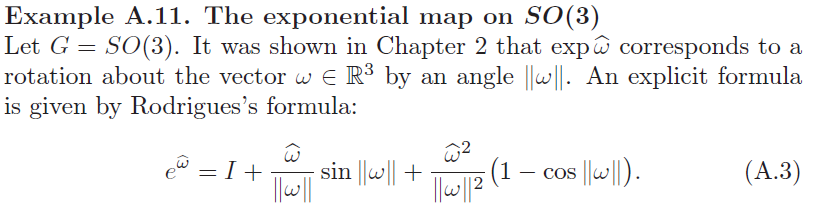

omega = sym('omega', [3 1], 'real') 

$$omega = \left(\begin{array}{c} \omega_{1}\\ \omega_{2}\\ \omega_{3} \end{array}\right)$$

sympref('HeavisideAtOrigin', realmin);
%symnorm = @(v) heaviside(sqrt(dot(v,v)));  %% heaviside(0) == realmin
symnorm = @(v) (sqrt(dot(v,v))+sqrt(realmin)); %% sqrt(realmin) because we need symnorm(omega)^2 to not be 0 in the exception case
unit = @(v) v./symnorm(v);     
symnorm

symnorm = function_handle with value:
    @(v)(sqrt(dot(v,v))+sqrt(realmin))

Rodrigues= eye(3)...     
    +(f_skew(omega) /symnorm(omega)) * sin(symnorm(omega))...
    +((f_skew(omega)^2) /symnorm(omega)^2) * (1 - cos(symnorm(omega)) )

$$Rodrigues = \begin{array}{l} \left(\begin{array}{ccc} \frac{\left(\cos\left(\sigma_{7}\right)-1\right)\,\left({\omega_{2}}^{2}+{\omega_{3}}^{2}\right)}{{\sigma_{7}}^{2}}+1 & -\sigma_{4}-\sigma_{3} & \sigma_{5}-\sigma_{2}\\ \sigma_{4}-\sigma_{3} & \frac{\left(\cos\left(\sigma_{7}\right)-1\right)\,\left({\omega_{1}}^{2}+{\omega_{3}}^{2}\right)}{{\sigma_{7}}^{2}}+1 & -\sigma_{6}-\sigma_{1}\\ -\sigma_{5}-\sigma_{2} & \sigma_{6}-\sigma_{1} & \frac{\left(\cos\left(\sigma_{7}\right)-1\right)\,\left({\omega_{1}}^{2}+{\omega_{2}}^{2}\right)}{{\sigma_{7}}^{2}}+1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\omega_{2}\,\omega_{3}\,\left(\cos\left(\sigma_{7}\right)-1\right)}{{\sigma_{7}}^{2}}\\ \sigma_{2}=\frac{\omega_{1}\,\omega_{3}\,\left(\cos\left(\sigma_{7}\right)-1\right)}{{\sigma_{7}}^{2}}\\ \sigma_{3}=\frac{\omega_{1}\,\omega_{2}\,\left(\cos\left(\sigma_{7}\right)-1\right)}{{\sigma_{7}}^{2}}\\ \sigma_{4}=\frac{\omega_{3}\,\sin\left(\sigma_{7}\right)}{\sigma_{7}}\\ \sigma_{5}=\frac{\omega_{2}\,\sin\left(\sigma_{7}\right)}{\sigma_{7}}\\ \sigma_{6}=\frac{\omega_{1}\,\sin\left(\sigma_{7}\right)}{\sigma_{7}}\\ \sigma_{7}=\sqrt{{\omega_{1}}^{2}+{\omega_{2}}^{2}+{\omega_{3}}^{2}}+\frac{1}{6703903964971298549787012499102923063739682910296196688861780721860882015036773488400937149083451713845015929093243025426876941405973284973216824503042048} \end{array}$$

SO3.Exp = matlabFunction(Rodrigues, 'Vars', {omega})

SO3 = struct with fields:
      Skew: @(v)f_skew(v)
    unSkew: @(A)f_deskew(A)
       Exp: [function_handle]


%%% mimmo: we need to test this function: PROBLEMS
R1 = SO3.Exp (0*rand(3,1));
det(R1)

ans =      1

 R1*R1'      %% does not return identity

ans =      1     0     0
     0     1     0
     0     0     1


## SO(3) Logarithm

R = sym('R', [3 3], 'real')

$$R = \left(\begin{array}{ccc} R_{1,1} & R_{1,2} & R_{1,3}\\ R_{2,1} & R_{2,2} & R_{2,3}\\ R_{3,1} & R_{3,2} & R_{3,3} \end{array}\right)$$

theta=heaviside( acos((trace(R)-1)/2) )    %% heaviside(0) == realmin

$$theta = \mathrm{heaviside}\left(\mathrm{acos}\left(\frac{R_{1,1}}{2}+\frac{R_{2,2}}{2}+\frac{R_{3,3}}{2}-\frac{1}{2}\right)\right)$$

r = f_deskew(R-R')/sin(theta)/2

$$r = \begin{array}{l} \left(\begin{array}{c} -\frac{R_{2,3}-R_{3,2}}{\sigma_{1}}\\ \frac{R_{1,3}-R_{3,1}}{\sigma_{1}}\\ -\frac{R_{1,2}-R_{2,1}}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=2\,\sin\left(\mathrm{heaviside}\left(\mathrm{acos}\left(\frac{R_{1,1}}{2}+\frac{R_{2,2}}{2}+\frac{R_{3,3}}{2}-\frac{1}{2}\right)\right)\right) \end{array}$$

SO3.Logvee = matlabFunction(r, 'Vars',{R})

SO3 = struct with fields:
      Skew: @(v)f_skew(v)
    unSkew: @(A)f_deskew(A)
       Exp: [function_handle]
    Logvee: [function_handle]

## Group of rigid body transformations SE(3)

The group of rigid body motions (not just rotation) is the special Eucledian group SE(3). 


$$SE(3)=\{
T = 
\left[
  \begin{array}{cc}
  R & p  \\
  0 & 1 
  \end{array}
\right]
\in {\bf R}^{4\times 4} 

: R \in SO(3), p\in {\bf R}^3\}$$


H4x4 = sym('H', [4 4], 'real')

$$H4x4 = \left(\begin{array}{cccc} H_{1,1} & H_{1,2} & H_{1,3} & H_{1,4}\\ H_{2,1} & H_{2,2} & H_{2,3} & H_{2,4}\\ H_{3,1} & H_{3,2} & H_{3,3} & H_{3,4}\\ H_{4,1} & H_{4,2} & H_{4,3} & H_{4,4} \end{array}\right)$$

SE3.Rot = @(T) T(1:3, 1:3)

SE3 = struct with fields:
    Rot: @(T)T(1:3,1:3)

% which returns
SE3.Rot (H4x4)

$$ans = \left(\begin{array}{ccc} H_{1,1} & H_{1,2} & H_{1,3}\\ H_{2,1} & H_{2,2} & H_{2,3}\\ H_{3,1} & H_{3,2} & H_{3,3} \end{array}\right)$$

SE3.Pos = @(T) T(1:3, 4);
SE3.Pos (H4x4);
SE3.RotPos2T = @(Rot, Pos) [Rot, Pos; 0 0 0 1];
T1 = SE3.RotPos2T (R, a) 

$$T1 = \left(\begin{array}{cccc} R_{1,1} & R_{1,2} & R_{1,3} & a_{1}\\ R_{2,1} & R_{2,2} & R_{2,3} & a_{2}\\ R_{3,1} & R_{3,2} & R_{3,3} & a_{3}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

The inverse of a member of SE(3) is derived to be:

SE3.inv = @ (T) SE3.RotPos2T(SE3.Rot(T)', -SE3.Rot(T)'*SE3.Pos(T));


%% functions need to be tested, always, e.g.
T2 = SE3.RotPos2T (SO3.Exp(rand(3,1)), rand(3,1));
assume (a(1), 'positive'); %% to get rid of the 'heaviside' function
SE3.inv (T2)* T2

ans =                          1     -1.11022302462516e-16     -2.77555756156289e-17     -6.93889390390723e-17
     -1.11022302462516e-16                         1      5.55111512312578e-17                         0
     -2.77555756156289e-17      5.55111512312578e-17                         1                         0
                         0                         0                         0                         1


## Screw axis based Transformation matrix

The **Chasles-Mozzi theorem** states that every rigid-body displacement can be expressed as a displacement along a fixed screw axis S in space. 

Here, $v$ is the lineary velocity of the body denoted in the screw axis representation. It is important to choose $q$ appropriately so that the right. It might be useful to define

q = sym('q', [3 1], 'real')

$$q = \left(\begin{array}{c} q_{1}\\ q_{2}\\ q_{3} \end{array}\right)$$

% if omega=omega_hat*theta
v = @(omega,q) SO3.Skew(-unit(omega))*q

v = function_handle with value:
    @(omega,q)SO3.Skew(-unit(omega))*q


%*norm(omega)+(1-cos(norm(omega)))*SO3.Skew(unit(omega))+(norm(omega)-sin(norm(omega)))*SO3.Skew(unit(omega))^2)*v(omega,q);
SE3Exp = @ (omega,q) [SO3.Exp(omega)    (eye(3)*norm(omega)+((1-cos(norm(omega)))*SO3.Skew(unit(omega)))+((norm(omega)-sin(norm(omega)))*SO3.Skew(unit(omega))^2))*v(omega,q);
    0 0 0 1]

SE3Exp = function_handle with value:
    @(omega,q)[SO3.Exp(omega),(eye(3)*norm(omega)+((1-cos(norm(omega)))*SO3.Skew(unit(omega)))+((norm(omega)-sin(norm(omega)))*SO3.Skew(unit(omega))^2))*v(omega,q);0,0,0,1]

SE3.Exp = @ (omega,q) SE3Exp(omega,q);
%Verification
%w = sym('w', [3 1], 'real')
%SE3.inv(SE3.Exp(w,q))*SE3.Exp(w,q)

## Adjoint of a Transformation

It is useful to observe the property of the product $T^{-1}\dot{T}$. This helps in derving the relation between the body twists and space twists, known as the adjoint representation.

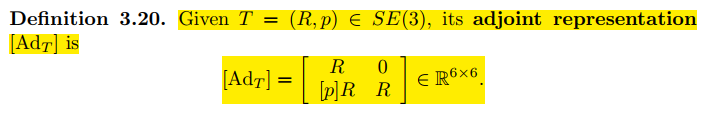

T = sym('T', [6 6], 'real')

$$T = \left(\begin{array}{cccccc} T_{1,1} & T_{1,2} & T_{1,3} & T_{1,4} & T_{1,5} & T_{1,6}\\ T_{2,1} & T_{2,2} & T_{2,3} & T_{2,4} & T_{2,5} & T_{2,6}\\ T_{3,1} & T_{3,2} & T_{3,3} & T_{3,4} & T_{3,5} & T_{3,6}\\ T_{4,1} & T_{4,2} & T_{4,3} & T_{4,4} & T_{4,5} & T_{4,6}\\ T_{5,1} & T_{5,2} & T_{5,3} & T_{5,4} & T_{5,5} & T_{5,6}\\ T_{6,1} & T_{6,2} & T_{6,3} & T_{6,4} & T_{6,5} & T_{6,6} \end{array}\right)$$

Ad = @ (T) [SE3.Rot(T) zeros(3,3);
    SO3.Skew(SE3.Pos(T))*SE3.Rot(T)   SE3.Rot(T)]

Ad = function_handle with value:
    @(T)[SE3.Rot(T),zeros(3,3);SO3.Skew(SE3.Pos(T))*SE3.Rot(T),SE3.Rot(T)]

SE3.Ad = @(T) Ad(T)

SE3 = struct with fields:
         Rot: @(T)T(1:3,1:3)
         Pos: @(T)T(1:3,4)
    RotPos2T: @(Rot,Pos)[Rot,Pos;0,0,0,1]
         inv: @(T)SE3.RotPos2T(SE3.Rot(T)',-SE3.Rot(T)'*SE3.Pos(T))
         Exp: @(omega,q)SE3Exp(omega,q)
          Ad: @(T)Ad(T)

## SE(3) Logarithm

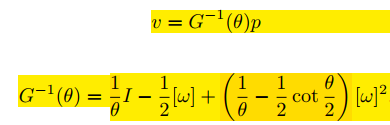

SE3omega = @(T) SO3.Logvee(T(1:3,1:3));
SE3theta = @(T) heaviside( acos((trace(T(1:3,1:3))-1)/2) );
SE3.Ginv = @(omega,theta) (eye(3)/theta - SO3.Skew(omega(1:3,1))/2 + (1/theta - 1/2*cot(theta/2))*SO3.Skew(omega)^2);

theta=SE3theta(T);
SE3.Log = @(T) SE3.Ginv(SE3omega(T),SE3theta(T))*T(1:3,4)

SE3 = struct with fields:
         Rot: @(T)T(1:3,1:3)
         Pos: @(T)T(1:3,4)
    RotPos2T: @(Rot,Pos)[Rot,Pos;0,0,0,1]
         inv: @(T)SE3.RotPos2T(SE3.Rot(T)',-SE3.Rot(T)'*SE3.Pos(T))
         Exp: @(omega,q)SE3Exp(omega,q)
          Ad: @(T)Ad(T)
        Ginv: @(omega,theta)(eye(3)/theta-SO3.Skew(omega(1:3,1))/2+(1/theta-1/2*cot(theta/2))*SO3.Skew(omega)^2)
         Log: @(T)SE3.Ginv(SE3omega(T),SE3theta(T))*T(1:3,4)

SO3

SO3 = struct with fields:
      Skew: @(v)f_skew(v)
    unSkew: @(A)f_deskew(A)
       Exp: [function_handle]
    Logvee: [function_handle]

SE3

SE3 = struct with fields:
         Rot: @(T)T(1:3,1:3)
         Pos: @(T)T(1:3,4)
    RotPos2T: @(Rot,Pos)[Rot,Pos;0,0,0,1]
         inv: @(T)SE3.RotPos2T(SE3.Rot(T)',-SE3.Rot(T)'*SE3.Pos(T))
         Exp: @(omega,q)SE3Exp(omega,q)
          Ad: @(T)Ad(T)
        Ginv: @(omega,theta)(eye(3)/theta-SO3.Skew(omega(1:3,1))/2+(1/theta-1/2*cot(theta/2))*SO3.Skew(omega)^2)
         Log: @(T)SE3.Ginv(SE3omega(T),SE3theta(T))*T(1:3,4)

%SE3.Log([1 0 0 1;0 1 0 0;0 0 1 0;0 0 0 1])

save('SO3.mat', 'SO3');
save('SE3.mat','SE3');

